clear

syms theta1 theta2 theta3 theta4 theta5 theta6

A = [  0     -1      0.15
      200     0      0
     theta3 theta4 theta5 ];
B = [  0
       0
     theta6];
C = [0 1 0];
graybox = struct('A',A,'B',B,'C',C);
clear theta1 theta2 theta3 theta4 theta5 theta6

A = [-19.42  5.333    3.505
     -12.13 -0.6035 -11.48
      16.31 14.9     -4.98 ];
B = [-1.722
     -0.6439
      1.727 ];
C = [10.85 -6.926 8.238];
blackbox = ss(A,B,C,0);
clear A B C

sol = ssGrayId(blackbox, graybox, 'Method','nullspace');


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


disp(sol.parameters.')

$$\left(\begin{array}{cccc} \theta_{3} & \theta_{4} & \theta_{5} & \theta_{6} \end{array}\right)$$

disp(sol.parameter_values.')

 -600.0818   -9.9715  -25.0035  -99.9352



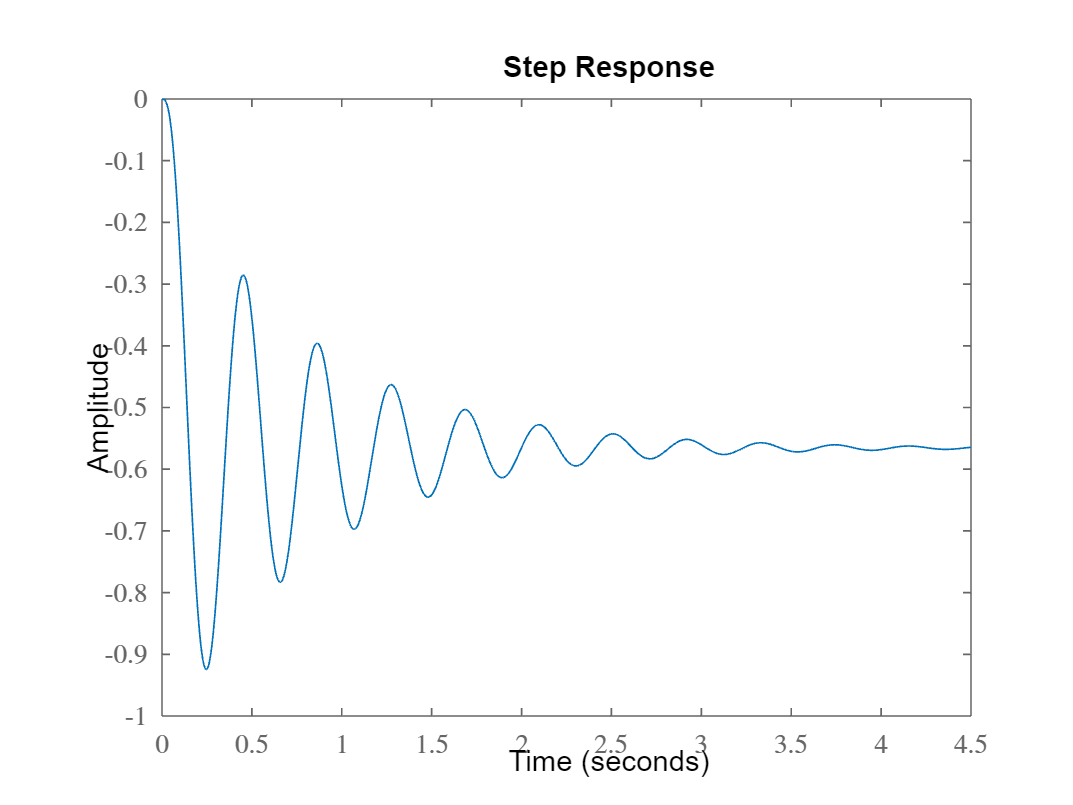


figure
step(blackbox)

figure
step(sol.sys)